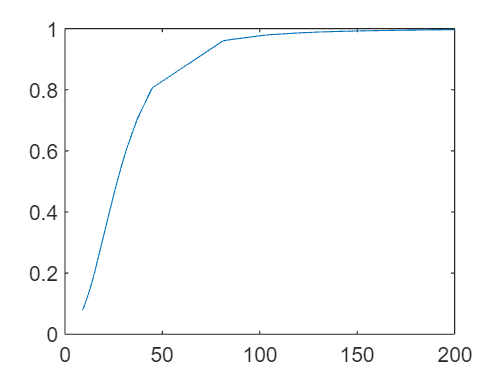

ans = [];
PO2_range = 1:1:200;

real_range = [];
real_S = [];
for PO2 = PO2_range
    eqn = -0.385*log((1 - S)/S) + 3.32 - (1/(72*S)) - S^6/6 == log(PO2);
    O_Sat = vpasolve(eqn,S);
    if (imag(O_Sat)) == 0i
        real_range(end+1) = PO2;
        real_S(end+1) = O_Sat;
    end
end

plot(real_range, real_S)